**!!! IMPORTANT !!!**

**Before running this Live script, run the 1st demo ("a010_Basics_ParameterManagment_Solving_RunIDs.mlx") in order to get expected solutions in the CST project, if you haven't done so.**

clc
clear

Connect to the project

CSTProject = 'CST\Single_dipole.cst';
CST = TCSTInterface();
CST.OpenProject(CSTProject);

Connected to project "E:\01_Toolboxes\CSTMWS-Matlab-Interface\Demos\CST\Single_dipole.cst"


# Getting far-field

**NOTE****: The full far-field is stored in CST only**** for the current run****!** 

The far-field can be exported using `ExportFarField` method of the interface, full syntax of which is following:

All arguments are optional and can be set to empty array to apply default settings.

The arguments are:

- `OutputFileName:` The far-field will be saved to CST's "far-field source" file (*.ffs) specified in `OutputFileName`. Default value is [], i.e. do not save into a file.

- `SaveBroadband`: Can be `true` or `false` (default). When it is set to true, the far-field from the broadband field monitor will be read. If `SaveBroadband` is false or [], the broadband field monitor will be ignored, and far-field will be read from all single-frequency monitors.

- `ThetaPhiStepDeg`: 1x2 vector, specifying step in Theta and Phi, [deg]. Default value is `[5 5]`.

- `NormalizationType`: Specifies how the exported far-field should be normalized. See details below this list. The field normalization is not applied by default.

- `SaveToMat`: Can be `true` or `false` (default). It shows if the output of this function should be saved to a mat-file. Makes effect only when `OutputFileName` is specified.

 `NormalizationType` can take the following values:

- `'None'` or `[] `(default): No field normalization is applied. The field units are [V], or [dBV] when plotted in dB-scale.

- `'Directivity'`: The field power is normalized to the total radiated power, so the `Field` structure contains directivity patterns. If the field is plotted in dB, the units are [dBi].

- `'Gain'`: The field power is normalized to the accepted power, so the `Field` structure contains gain patterns. If the field is plotted in dB, the units are [dBi].

- `'RealizedGain'`: The field power is normalized to the source available power, so the `Field` structure contains realized gain patterns. If the field is plotted in dB, the units are [dBi].

- `'Unity'`: The field magnitude is normalized to its maximum value over directions. This is done in a per-frequency basis. The field units are [-], or [dB] when plotted in dB-scale.

In the command below we read the far-field from all available single-frequency (because `SaveBroadband=false` by default) monitors with 5 deg step in Theta and Phi:

[Field, Info] = CST.ExportFarField();

Reading "TempFarField_0p8_Exc1.ffs": Freq = 1 of 1 (800.000 MHz)
Reading "TempFarField_1p2_Exc1.ffs": Freq = 1 of 1 (1200.000 MHz)


The first output argument is the Field-structure containing the far-field values, angles, field components notation and other information. See the PDF-file "[Field_structure_description_with_appendix.pdf](matlab: winopen('Field_structure_description_with_appendix.pdf'))" for detailed description of the Field-structure format.

Field

Field = struct with fields:
                Freq: [800000000 1.2000e+09]
                   E: [5-D double]
               THETA: [37×73 double]
                 PHI: [37×73 double]
    VectorComponents: 'spherical'
       PortImpedance: []
             NearFar: 'far'
            GridType: 'spherical'
        GridSymmetry: 'unsymmetrical'


size(Field.E)

ans =     37    73     3     1     2


In short, the field above is stored in spherical coordinate system (`Field.GridType='spherical'`), the field vectors are stored as their pho-, theta- and phi-components (`Field.VectorComponents='theta-phi'`). The far-field is in the matrix `Field.E`, dimension sizes of which correspond to: 1: number of theta-points; 2: number of phi-points; 3: number of the field components (rho-, theta- and phi-components); 4: number of ports or excitations; 5: number of frequencies.

The 2nd output argument is a structure with additional information about the radiation patterns, which is obtained from CST. Below there is the info for 1st pattern of our project (1st frequency):

Info(1) 

ans = struct with fields:
           FileName: 'C:\Users\Oleg\AppData\Local\Temp\CST_FFS_files\TempFarField_0p8_Exc1.ffs'
               Freq: 800000000
      RadiatedPower: 0.1745
      AcceptedPower: 0.1744
    StimulatedPower: 0.5000
      CoorSysOrigin: [3×1 double]
       CoorSysZAxis: [3×1 double]
       CoorSysXAxis: [3×1 double]


Let's plot the field power in a uv-like projection, where radial and azimuthal coordinates correspond to $\theta$ and $\phi$, respectively:

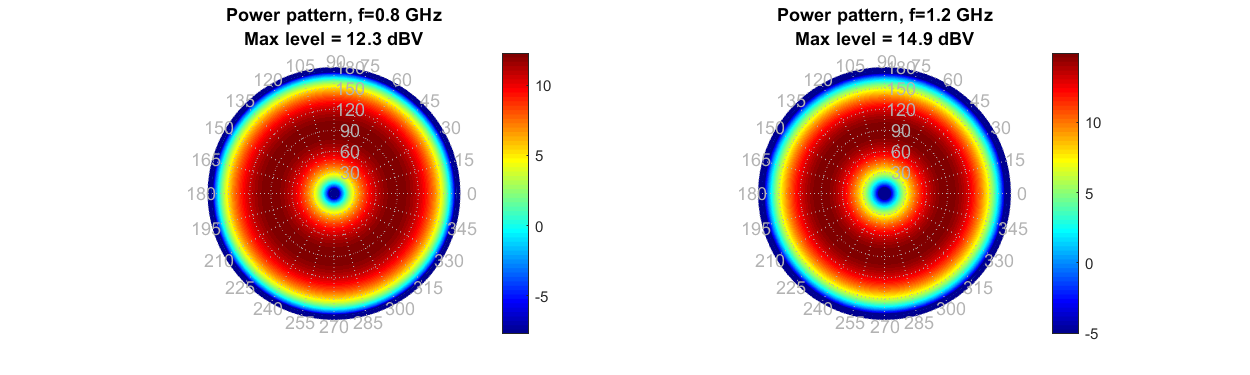

figure('Position',[20 20 1000 300]); 
subplot(1,2,1);  localPlotField(Field, 1, 1, 'dBV'); % pattern for 1st frequency
subplot(1,2,2);  localPlotField(Field, 1, 2, 'dBV'); % pattern for 2nd frequency

As expected for a z-oriented dipole, there is no radiation in $\theta=0^\circ$ and $\theta=180^\circ$, and maximum in for $\theta=90^\circ$.

Below we read the directivity patterns (`NormalizationType = 'Directivity'`) from the broadband field monitor (`SaveBroadband = true`).

[Field, Info] = CST.ExportFarField([],true,[],'Directivity');

Reading "TempFarField_broadband_Exc1.ffs": Freq = 1 of 5 (750.000 MHz)
Reading "TempFarField_broadband_Exc1.ffs": Freq = 2 of 5 (800.000 MHz)
Reading "TempFarField_broadband_Exc1.ffs": Freq = 3 of 5 (1000.000 MHz)
Reading "TempFarField_broadband_Exc1.ffs": Freq = 4 of 5 (1200.000 MHz)
Reading "TempFarField_broadband_Exc1.ffs": Freq = 5 of 5 (1250.000 MHz)


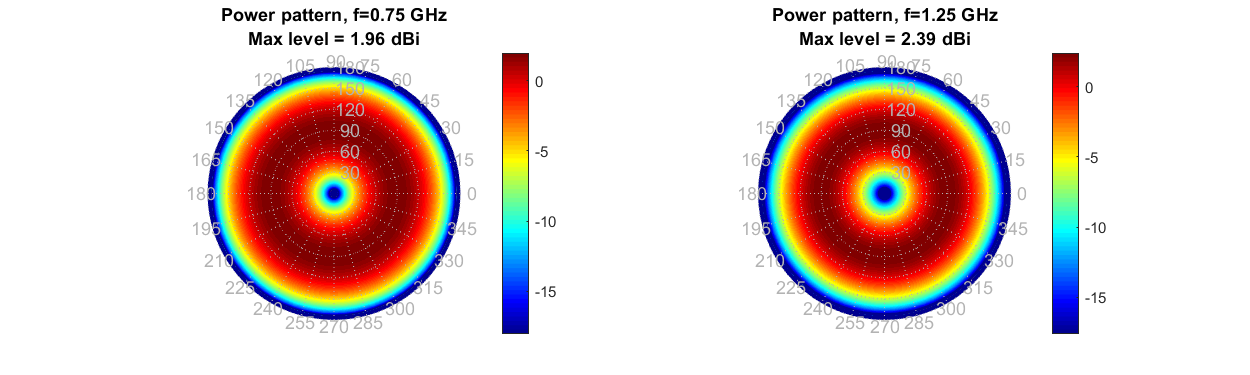


figure('Position',[20 20 1000 300]); 
subplot(1,2,1);  localPlotField(Field, 1, 1, 'dBi'); % pattern for 1st frequency
subplot(1,2,2);  localPlotField(Field, 1, 5, 'dBi'); % pattern for 5th frequency

Similarly, we can use other field normalizations.

## Helping functions

This function plots the 3D pattern projected in uv-like grid:

function localPlotField(Field, iPort, iFreq, Units)
    
    % Plot pattern surface
    [X,Y] = pol2cart(Field.PHI, Field.THETA);
    X = rad2deg(X);    Y = rad2deg(Y);
    Z = 10*log10(squeeze( sum( abs(Field.E(:,:,:,iPort,iFreq)).^2, 3 ) ));
    hSurf = surface(X, Y, Z, 'FaceColor','interp', 'EdgeAlpha',0);
    % some adjustments
    view([0 0 1]);  colormap jet;  colorbar;  axis equal off;  hold on;  
    Dmax = max(Z(:));  caxis([Dmax-20 Dmax]); % show in 20 dB dynamic range
    % add title with some info
    title({...
        sprintf('Power pattern, f=%g GHz',Field.Freq(iFreq)/1e9) ...
        sprintf('Max level = %.3g %s',Dmax,Units);
    });
    
    % Plot grid: theta-circles
    Theta = 30:30:180;  NTheta = length(Theta);  ThMax = max(Theta);  ThMin = min(Theta);
    ph = (0:1:360).'; 
    Nph = length(ph);
    R = [ones(Nph,NTheta); nan(1,NTheta)];
    R = bsxfun(@times, R, Theta);
    x = bsxfun(@times, R, cosd([ph; nan]));
    y = bsxfun(@times, R, sind([ph; nan]));
    plot3(x(:),y(:),Dmax+0*x(:), ':', 'Color',[1 1 1]*0.7);
    % theta labels
    ThetaT = Theta; ThetaT(Theta==0)=[];
    text(ThetaT*0+0.01*ThMax, ThetaT, Dmax+0*ThetaT(:), num2str(ThetaT.'), 'Color',[1 1 1]*0.7,...
        'HorizontalAlignment','left','VerticalAlignment','middle', 'FontSize',11, 'FontWeight','normal');
    
    % Plot grid: phi-lines
    Phi = 0:15:359;  NPhi = length(Phi);
    x = nan(3,NPhi);  y = x;
    x(1,:) = ThMin .* cosd(Phi);    x(2,:) = ThMax .* cosd(Phi);
    y(1,:) = ThMin .* sind(Phi);    y(2,:) = ThMax .* sind(Phi);
    plot3(x(:),y(:),Dmax+0*x(:), ':', 'Color',[1 1 1]*0.7);
    % phi labels
    text(1.05*x(2,:), 1.05*y(2,:), Dmax+0*x(2,:), num2str(Phi.'), 'Color',[1 1 1]*0.7,...
        'HorizontalAlignment','center','VerticalAlignment','middle', 'FontSize',11, 'FontWeight','normal');
end